## **System + data**

% Define system components
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 20, 'BitsPerSymbol', 2);

% Define raised cosine filters
span = 2;                 % Filter span (number of symbols)
samplesPerSymbol = 8;      % Samples per symbol
rolloff = 0.5;               % Rolloff factor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', 1);

symbolSync = comm.SymbolSynchronizer( ...
    'Modulation','OQPSK', ...
    'SamplesPerSymbol', samplesPerSymbol, ...
    'DampingFactor', 1, ...
    'NormalizedLoopBandwidth', 0.01, ...
    'TimingErrorDetector', 'Mueller-Muller (decision-directed)');

% Generate a random binary sequence
numBits = 128;
payload = randi([0 1], numBits, 1);

sequenceLength = 8;
barker=comm.BarkerCode("Length",7,'SamplesPerFrame', sequenceLength)

barker =   comm.BarkerCode with properties:

             Length: 7
    SamplesPerFrame: 8
     OutputDataType: 'double'


barkerCode= (barker()+ 1) / 2

barkerCode =      0
     0
     0
     1
     1
     0
     1
     0


barkerSignal=oqpskmod(barkerCode);

data=[barkerCode; payload];

if mod(length(data), 2) ~= 0
    data = [data; 0];  % Padding with zero to make the length even
end

## Transmitter

% Modulate the signal
txSignal = oqpskmod(data);

% Filter the signal at the transmitter
txFilteredSignal = txFilter(txSignal);

% Parameters for phase shift and frequency shift
randomPhaseShift = -180 + 360*rand();  % Random phase shift
minFreqShift = -100;  % Minimum frekvensforskyvning i Hz
maxFreqShift = 100;   % Maksimum frekvensforskyvning i Hz
freqShift = minFreqShift + (maxFreqShift - minFreqShift) * rand();

% Apply frequency shift and phase shift, and simulate delay
phaseFreqOffset= comm.PhaseFrequencyOffset('FrequencyOffset', 0, 'PhaseOffset', randomPhaseShift);

txSignalWithOffset = phaseFreqOffset(txFilteredSignal);

## Receiver

% Pass the phase-shifted signal through the AWGN channel and filter
rxSignal = rxFilter(channel(txSignalWithOffset));


### Phase-Synchronize

correlation = xcorr(barkerSignal,rxSignal);

% Finn tidspunktet for maksimumet i korrelasjonen
[~, maxIndex] = max(abs(correlation));

### Frequency-Synchronize

### Frame-Synchronize

corr = xcorr(rxSignal,barkerSignal);
[~,lag_idx]=max(corr);

# Time-Series

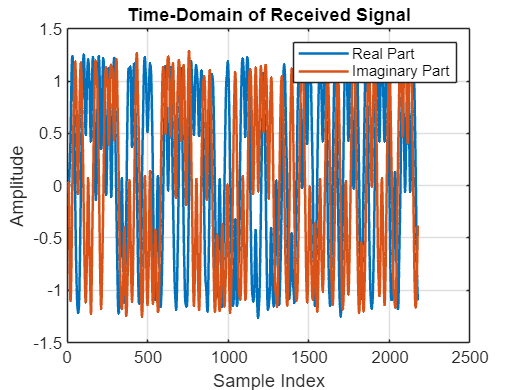

figure;
plot(real(rxSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
grid on;
hold off;

# PSD

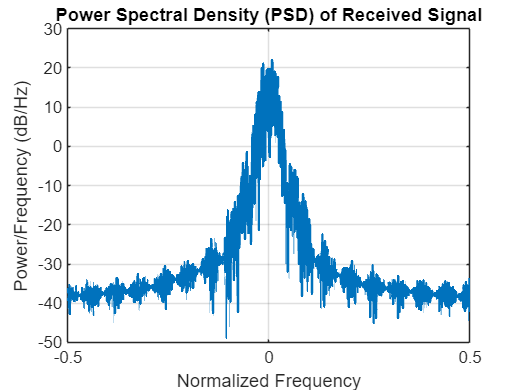

figure;
[psdValues, psdFreq] = periodogram(rxSignal, [], [], 1, 'centered'); % Bruk periodogram for PSD
plot(psdFreq, 10*log10(psdValues), 'LineWidth', 1.5);
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

# Constellation

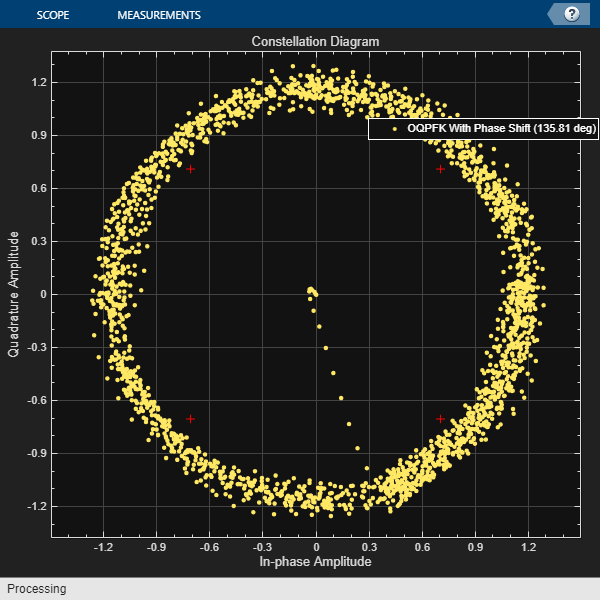

constDiagram = comm.ConstellationDiagram( ...
    'ShowLegend', true, ...
    'Title', 'Constellation Diagram', ...
    'ChannelNames', { ...
        sprintf('OQPFK With Phase Shift (%.2f deg)', phaseShiftDeg)});

constDiagram(rxSignal);

# Eye-Diagram

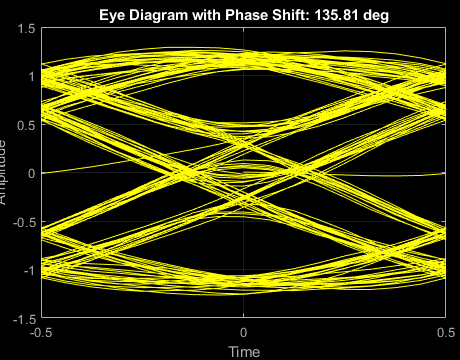

figure;
eyediagram(real(rxSignal), samplesPerSymbol * span);
title(sprintf('Eye Diagram with Phase Shift: %.2f deg', phaseShiftDeg)); 
xlabel('Time');
ylabel('Amplitude');
grid on;